close all
clear vars
clc
disp('Elias Assaf 315284729 - Jameel Nassar 206985152');

Elias Assaf 315284729 - Jameel Nassar 206985152



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Section 1

We used the famous painting 'The Starry Night' as the manipulated image.

To normalize the inmage we used the same equations from EX1, to separate the color channels we used indexing on the rgb image data.

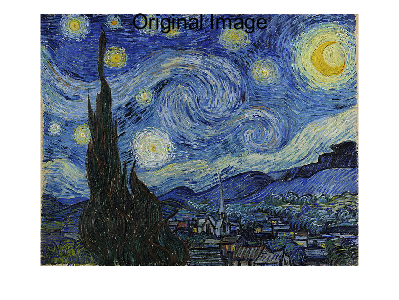

img = double(imread("starry_night.png"));
[rgb_img, r_img, g_img, b_img] = dip_normalize_rgb_img(img);
figure;sgtitle('Original Image');imshow(rgb_img);

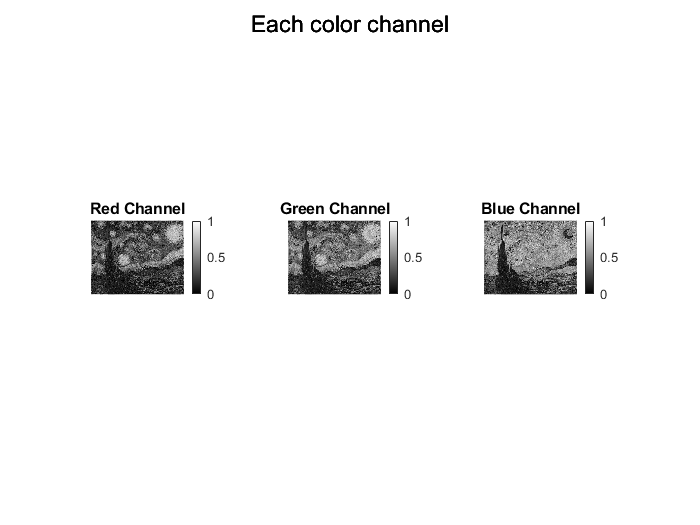

figure;colorbar;sgtitle('Each color channel');
subplot(1,3,1);imshow(r_img);title('Red Channel');colorbar;
subplot(1,3,2);imshow(g_img);title('Green Channel');colorbar;
subplot(1,3,3);imshow(b_img);title('Blue Channel');colorbar;

We used the given equation to convert to RGB image and the rusults are very similar in the figures.

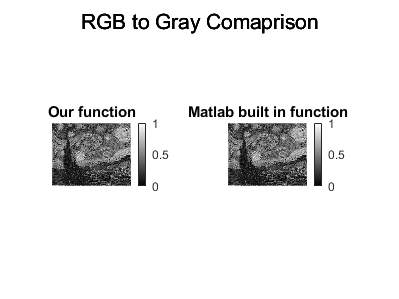

figure;sgtitle('RGB to Gray Comaprison');
subplot(1,2,1);imshow(dip_rgb2gray(rgb_img));title('Our function');colorbar;
subplot(1,2,2);imshow(rgb2gray(rgb_img));title('Matlab built in function');colorbar;

to check analytically we calculate the means of the difference between each pixel , and error margin is very small

error = mean(abs(dip_rgb2gray(rgb_img) - rgb2gray(rgb_img)),'all')

error = 3.5531e-05

Manipulating color channels.

The first Manipulation is very simple, we swapped the red and blue channels.

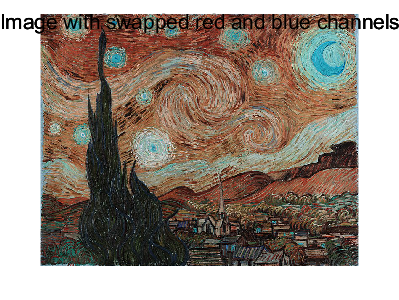

% switching blue and red channels
bgr_starry_night = cat(3, b_img,g_img,r_img);
figure;imshow(bgr_starry_night);sgtitle('Image with swapped red and blue channels');

As we can see in the figure the majority of blue colors turned to blue, the sky for example, also the yelllow stars turned to cyan, and we can conclude that cyan valuses consist of high green and blue valuse because the yellow color in rgb consist of high red and green value.

we can confirm this if we look at the data tips in the figures

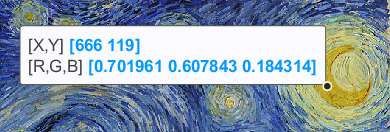

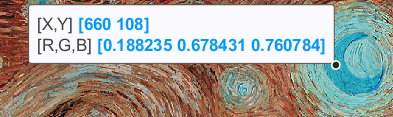

The second manipulation is using a swapping filter that inverts the values of the pixels

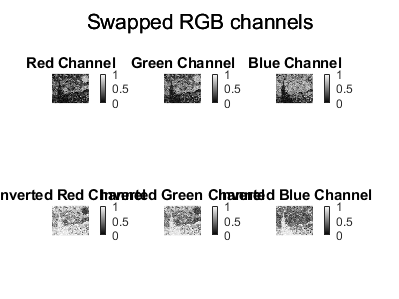

figure;sgtitle('Swapped RGB channels');
subplot(2,3,1);imshow(r_img);title('Red Channel');colorbar;
subplot(2,3,2);imshow(g_img);title('Green Channel');colorbar;
subplot(2,3,3);imshow(b_img);title('Blue Channel');colorbar;
subplot(2,3,4);imshow(r_img.*-1 +1);title('Inverted Red Channel');colorbar;
subplot(2,3,5);imshow(g_img.*-1 +1);title('Inverted Green Channel');colorbar;
subplot(2,3,6);imshow(b_img.*-1 +1);title('Inverted Blue Channel');colorbar;

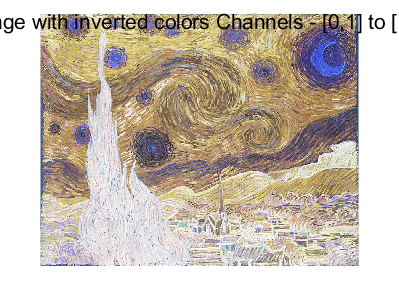


figure;imshow(rgb_img.*-1 + 1 );sgtitle('Image with inverted colors Channels - [0,1] to [1,0]');

The Third manipulation is applying a gaussian filter to the blue channel

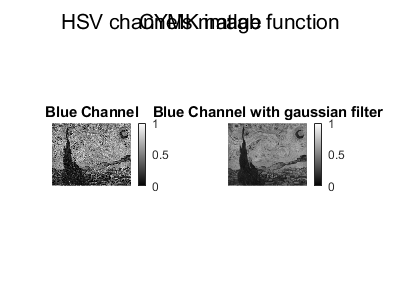

gaussian_b_img = dip_gaussian_filter(b_img,5,1);
gaussian_b_img = dip_gaussian_filter(gaussian_b_img,5,1);
gaussian_b_img = dip_gaussian_filter(gaussian_b_img,5,1);
gaussian_b_img = dip_gaussian_filter(gaussian_b_img,5,1);

figure;
subplot(1,2,1);imshow(b_img);title('Blue Channel');colorbar;
subplot(1,2,2);imshow(gaussian_b_img);title('Blue Channel with gaussian filter');colorbar;

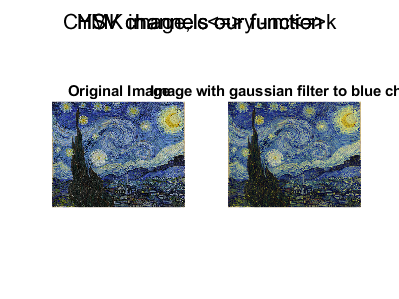


gaussian_img = cat(3, r_img,g_img,gaussian_b_img);
figure;
subplot(1,2,1);imshow(rgb_img);title('Original Image');
subplot(1,2,2);imshow(gaussian_img);title('Image with gaussian filter to blue channel');

As we can see in the figures, the gaussian filter smothed and blured the transition between the different blue color values which added a "glare" effect on the blue colors, and we can see that clearly in the sky. 

## Section 2

The CMYK color model refers to the four ink plates used in some color printing cyan, magenta, yellow, and key (black).

To create the CMYK channels we used the given equations 

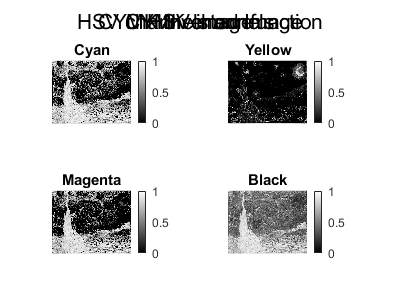

[c, y, m, k] = dip_rgb_to_cymk(r_img, g_img, b_img);
figure;sgtitle('CYMK channels');
subplot(2,2,1);imshow(c);title('Cyan');colorbar;
subplot(2,2,2);imshow(y);title('Yellow');colorbar;
subplot(2,2,3);imshow(m);title('Magenta');colorbar;
subplot(2,2,4);imshow(k);title('Black');colorbar;

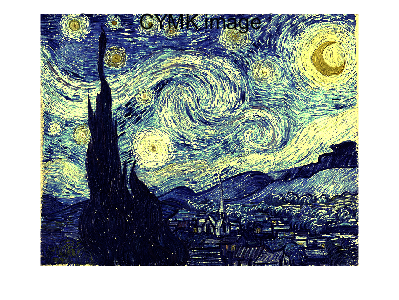


figure;sgtitle('CYMK image');
imshowCYMK(c,y,m,k);

Swapping the c channel with y channel and m channel with k channel.

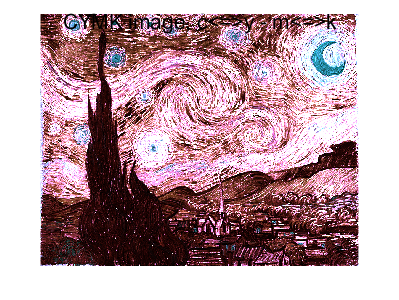

figure;sgtitle('CYMK image, c<=>y - m<=>k');
imshowCYMK(y,c,k,m);

Inverting the image

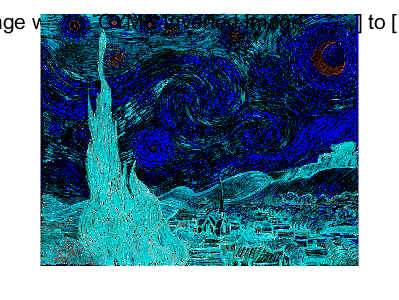

figure;sgtitle('CYMK Inverted Image');
imshowCYMK(y*-1 +1,c*-1 +1,k*-1 +1,m*-1 +1);

Applying guassian filter to the cyan channel

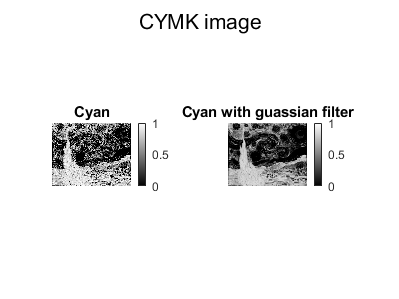

c_guassian = dip_gaussian_filter(c,5,1);
c_guassian = dip_gaussian_filter(c_guassian,5,1);
c_guassian = dip_gaussian_filter(c_guassian,5,1);
c_guassian = dip_gaussian_filter(c_guassian,5,1);

figure;
subplot(1,2,1);imshow(c);title('Cyan');colorbar;
subplot(1,2,2);imshow(c_guassian);title('Cyan with guassian filter');colorbar;

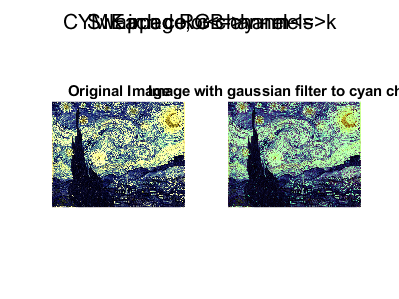


figure;
subplot(1,2,1);imshowCYMK(c,y,m,k);title('Original Image');
subplot(1,2,2);imshowCYMK(c_guassian,y,m,k);title('Image with gaussian filter to cyan channel');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Section 3

HSV color model consists of hue, saturation, value.

To convert from rgb to hsv we use the following equations

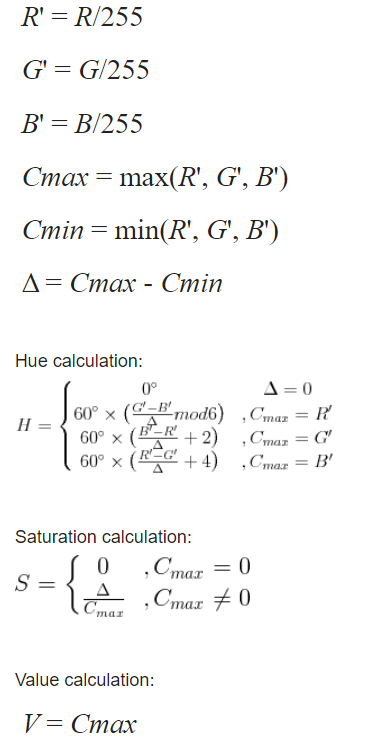

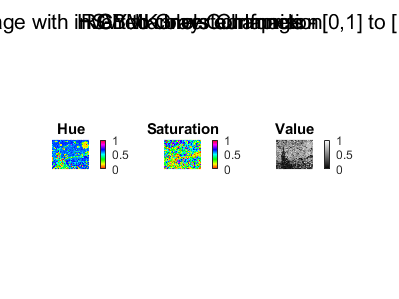

[h, s, v] = dip_rgb2hsv(r_img, g_img, b_img);
figure;sgtitle('HSV channels our function')
subplot(1,3,1);imshow(h);title('Hue');colormap('hsv');colorbar;
subplot(1,3,2);imshow(s);title('Saturation');colorbar;
subplot(1,3,3);imshow(v);title('Value');colorbar;

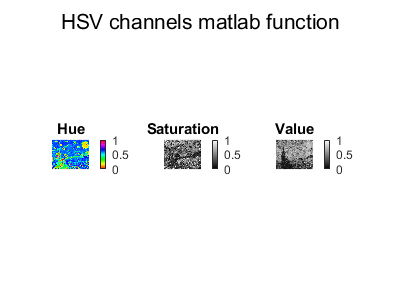


hsv_img = rgb2hsv(rgb_img);
figure;sgtitle('HSV channels matlab function')
subplot(1,3,1);imshow(hsv_img(:,:,1));title('Hue');colormap('hsv');colorbar;
subplot(1,3,2);imshow(hsv_img(:,:,2));title('Saturation');colorbar;
subplot(1,3,3);imshow(hsv_img(:,:,3));title('Value');colorbar;

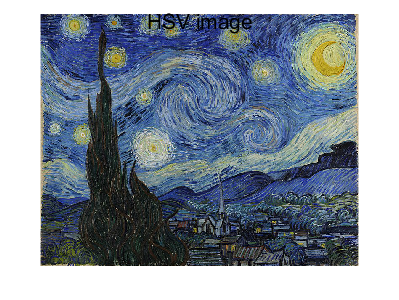


figure;sgtitle('HSV image');
imshowHSV(h,s,v);

3.6

%TODO: 3.6,
% 
% 
% 


Swapping the hue and saturation channel.

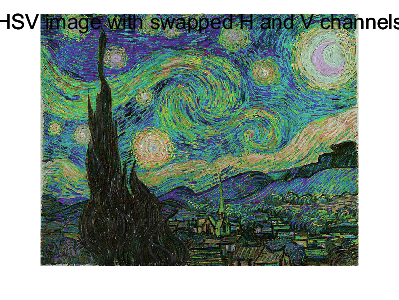

% 3.7
figure;sgtitle('HSV image with swapped H and V channels');
imshowHSV(s,h,v);

Inverting the channels

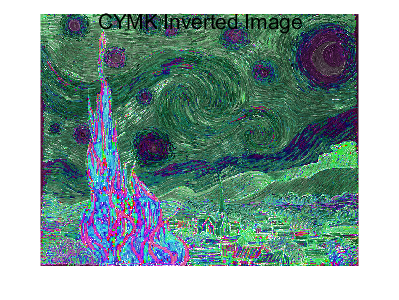

figure;sgtitle('CYMK Inverted Image');
imshowHSV(h*-1 +1,s*-1 +1,v*-1 +1)

Applying guassian filter to the value channel

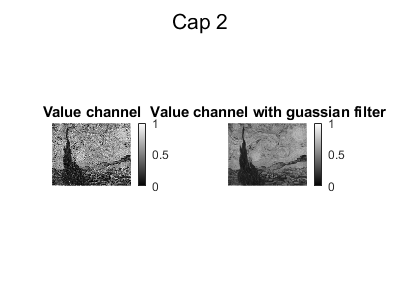

v_guassian = dip_gaussian_filter(v,5,1);
v_guassian = dip_gaussian_filter(v_guassian,5,1);
v_guassian = dip_gaussian_filter(v_guassian,5,1);
v_guassian = dip_gaussian_filter(v_guassian,5,1);

figure;
subplot(1,2,1);imshow(v);title('Value channel');colorbar;
subplot(1,2,2);imshow(v_guassian);title('Value channel with guassian filter');colorbar;

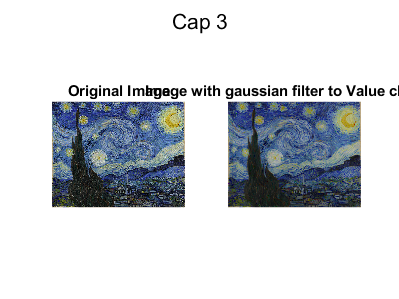


figure;
subplot(1,2,1);imshowHSV(h,s,v);title('Original Image');
subplot(1,2,2);imshowHSV(h,s,v_guassian);title('Image with gaussian filter to Value channel');

We can see in the figure the guassian filter was applied to all the colros,and thats because we applied it to Value channel which represents the strength of each color. 

## Section 4

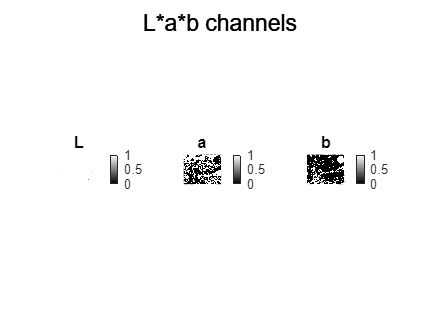

lab_img = rgb2lab(rgb_img);
figure;sgtitle('L*a*b channels')
subplot(1,3,1);imshow(lab_img(:,:,1));title('L');colorbar;
subplot(1,3,2);imshow(lab_img(:,:,2));title('a');colorbar;
subplot(1,3,3);imshow(lab_img(:,:,3));title('b');colorbar;

%TODO: 4.6

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Section 5

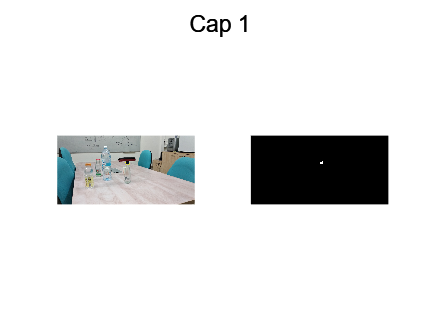

cap1 = double(imread("cap1.png"));
cap1_norm = dip_normalize_rgb_img(cap1);
[cap1_circled, cap1_filter] = dip_find_cap(cap1_norm);
figure;sgtitle('Cap 1')
subplot(1,2,1);title('Circled');imshow(cap1_circled);
subplot(1,2,2);title('Filter');imshow(cap1_filter);

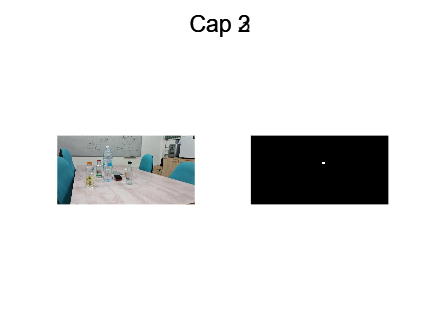


cap2 = double(imread("cap2.png"));
cap2_norm = dip_normalize_rgb_img(cap2);
[cap2_circled, cap2_filter] = dip_find_cap(cap2_norm);
figure;sgtitle('Cap 2')
subplot(1,2,1);title('Circled');imshow(cap2_circled);
subplot(1,2,2);title('Filter');imshow(cap2_filter);

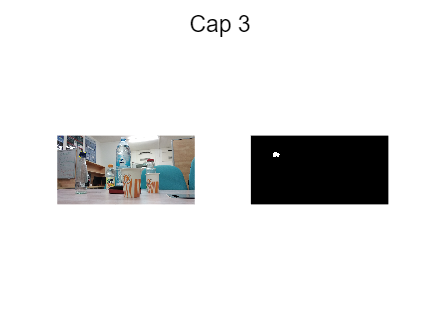


cap3 = double(imread("cap3.png"));
cap3_norm = dip_normalize_rgb_img(cap3);
[cap3_circled, cap3_filter] = dip_find_cap(cap3_norm);
figure;sgtitle('Cap 3')
subplot(1,2,1);title('Circled');imshow(cap3_circled);
subplot(1,2,2);title('Filter');imshow(cap3_filter);


%TODO: section 5

function [cap_img, filter] = dip_find_cap(img)
[cap_h, cap_s, cap_v] = dip_rgb2hsv(img(:,:,1), img(:,:,2), img(:,:,3));
cap_h_filt = zeros(size(cap_h));
cap_s_filt = zeros(size(cap_s));
cap_v_filt = zeros(size(cap_v));
cap_h_filt((cap_h > 0.6) & (cap_h < 0.7)) = 1;
cap_s_filt((cap_s > 0.40) & (cap_s < 0.88)) = 1;
cap_v_filt((cap_v > 0.07) & (cap_v < 0.30)) = 1;

filter = cap_h_filt .* cap_s_filt .* cap_v_filt;
filter = medfilt2(filter, [7 7]);

[x,y] = meshgrid(1:size(filter,2), 1:size(filter,1));
min_x = min(x(filter == 1));
max_x = max(x(filter == 1));
min_y = min(y(filter == 1));
max_y = max(y(filter == 1));

circle_x = floor((min_x+max_x)/2);
circle_y = floor((min_y+max_y)/2);

cap_img = insertShape(img, 'circle', [circle_x circle_y (max_x-circle_x + 3)]);
end
function [h, s, v] = dip_rgb2hsv(r, g, b)
%according to the equations stated in:
% https://www.rapidtables.com/convert/color/rgb-to-hsv.html
[C_max, I_max] = max(cat(3, r, g, b), [], 3);
C_min = min(cat(3, r, g, b), [], 3);
delta = C_max - C_min;
mask = (C_max ~= 0);
s = zeros(size(C_max));
s(mask) = delta(mask) ./ C_max(mask);
s(isnan(s)) = 0;

h = zeros(size(C_max));
r_mask = (I_max == 1);
h(r_mask) = mod( (g(r_mask)-b(r_mask)) ./ (delta(r_mask)), 6);
g_mask = (I_max == 2);
h(g_mask) =  2 + ((b(g_mask)-r(g_mask)) ./ (delta(g_mask)));
b_mask = (I_max == 3);
h(b_mask) =  4 + ((r(b_mask)-g(b_mask)) ./ (delta(b_mask)));
h(isnan(h)) = 0;
h = h/6;
v = C_max;
end

function [c, y, m, k] = dip_rgb_to_cymk(r, g, b)
k = min(cat(3, 1-r, 1-g, 1-b), [], 3);
c = (1-r-b)./(1-b);
m = (1-g-b)./(1-b);
y = (1-b-k)./(1-k);
end

function [norm_img, r, g, b] = dip_normalize_rgb_img(rgb_img)
r = dip_normalize_img(rgb_img(:,:,1));
g = dip_normalize_img(rgb_img(:,:,2));
b = dip_normalize_img(rgb_img(:,:,3));
norm_img = cat(3, r, g, b);
end

function [norm_img] = dip_normalize_img(img)
%normalize according to the equation given in the ex1 pdf
norm_img = (img - min(img(:)))./ (max(img(:)) - min(img(:)));
end


function [gray_img] = dip_rgb2gray(img)
gray_img = 0.2989 * img(:,:,1) + 0.5870 * img(:,:,2) + 0.1140 * img(:,:,3);
end


function [filtered_img] = filter(img, k, filt)
    to_extend = floor(k/2);
    %pad the matrix at the top and the bottom side, i.e. repeat the row line to_extend times at the top, and the end row to_extend times at the bottom
    filtered_img_y = [repmat(img(1, :), to_extend, 1) ; img; repmat(img(end, :), to_extend, 1)];
    %same for the left and right columns
    filtered_img_x = [repmat(filtered_img_y(:, 1), 1, to_extend), filtered_img_y , repmat(filtered_img_y(:, end), 1, to_extend)];
    filtered_img = zeros(size(filtered_img_x));
    %compute the convolution according to the equation seen in class
    for m=(1:size(img, 1))+to_extend
        for n=(1:size(img, 2))+to_extend
                filtered_img(m,n) = sum(filt .* filtered_img_x((m:m+k-1)-to_extend, (n:n+k-1)-to_extend), 'all');
        end
    end
    %cut the right values
    filtered_img = filtered_img( (1:size(img, 1))+to_extend, (1:size(img, 2))+to_extend);
    %clip the values if they become too big (gaussian with low sigma for
    %example)
    filtered_img(filtered_img > 1) = 1;
    filtered_img(filtered_img < 0) = 0;
end

function [filtered_img] = median_filter(img, k)
    to_extend = floor(k/2);
    %pad the matrix as in filter function
    filtered_img_y = [repmat(img(1, :), to_extend, 1) ; img; repmat(img(end, :), to_extend, 1)];
    filtered_img_x = [repmat(filtered_img_y(:, 1), 1, to_extend), filtered_img_y , repmat(filtered_img_y(:, end), 1, to_extend)];
    filtered_img = zeros(size(filtered_img_x));
    %for each coordinates m,n take a box matrix around the square and find the box median.
    for m=(1:size(img, 1))+to_extend
        for n=(1:size(img, 2))+to_extend
                filtered_img(m,n) = median(filtered_img_x((m:m+k-1)-to_extend, (n:n+k-1)-to_extend), 'all');
        end
    end
    %cut to original image size
    filtered_img = filtered_img( (1:size(img, 1))+to_extend, (1:size(img, 2))+to_extend);
end

function [filtered_img] = dip_gaussian_filter(img, k, sigma) %assume k is odd
    if mod(k,2) == 0
        error('filter size must be an odd number');
    end
    edges = floor(k/2);
    %use meshgrid to create 2 coords matrixes to calculate the gaussian distribution function
    [coords_x, coords_y] = meshgrid(-edges:edges, -edges:edges);
    filt = 1/(2 * pi * sigma^2) * exp(-(coords_x.^2 + coords_y.^2) / (2 * sigma^2));
    %use filter function
    filtered_img = filter(img, k, filt);
end